# Simulación de un reactor CSTR

**Autores: Bravo Erick, Jimenez Nancy, Paredes Nahir, Valencia Gabriel**

## **Introducción**

El modelado matemático es una herramienta que emplea varios métodos para caracterizar el comportamiento de distintos fenómenos dentro de un proceso determinado en el que permite estimar los parámetros involucrados (Boyadjiev, 2010). 

En el caso de ingeniería química los modelos matemáticos que se utilizan permiten caracterizar distintos procesos, entre los que se puede mencionar la termodinámica, fenómenos de transporte, etc (Boyadjiev, 2010). Los cuales están asociados a problemas de cálculo y requieren en repetidas ocasiones la resolución de ecuaciones diferenciales (ED). Entre los principales métodos numéricos empleados con el fin de resolver estos sistemas se encuentra el método de Euler, el cual parte de un valor inicial, seguido evalúa ecuaciones para obtener un resultado en el próximo valor; este proceso se realiza varias veces en un determinado intervalo para encontrar una solución aproximada a la resolución de la ED (Achieng, 2014).  

Los modelos matemáticos y la resolución con el método de Euler han sido ampliamente utilizados en el análisis del comportamiento de variables como Temperatura, Presión, Concentración, etc. En distintos sistemas, en el caso de estudio, se analizará un Reactor de Tanque Agitado Continuo (CSTR), el cual se caracteriza porque permite una mezcla constante de los reactivos y resulta en una producción continua y eficiente (Kirsty, 2023). 

Entre los principales puntos a considerar en un reactor CSTR, se encuentran que existe una mezcla perfecta y por otra parte que el reactor opera de manera continua, lo que permite que los reactivos fluyan constantemente y los productos sean extraídos simultáneamente, escenario en el cual el reactor se encuentra en estado estacionario al igual que la temperatura y concentración (Moran, 2017). Sin embargo, pueden existir factores que cambien dicho estado, en ese caso, habrá una denominada “perturbación” la cual se refiere a cambios que pueden afectar el comportamiento del sistema y en el tiempo generarán un nuevo estado estacionario. 

Finalmente, entre las principales consideraciones en un reactor CSTR se encuentra el tiempo de residencia y la velocidad de reacción, los cuales a su vez dependen de la temperatura y la concentración de los reactivos (Barragán et al., 2016). 

El objetivo de la simulación es mostrar cómo el sistema es afectado tras someterse a una perturbación en distintos casos, mediante la resolución de modelo matemático empleando el método de Euler. 

## Ejemplo

Se tiene un reactor cilíndrico cuyo volumen total es 45 $m^3$. En estado estacionario  el volumen del reactor es 39.6 $m^3$, de manera que la altura del líquido en el tanque  es de 3.5 m. La corriente de entrada al reactor tiene un caudal de 0.1 $\frac{m^3 }{s}$, una  concentración de 5000 kmol/s y una temperatura de 120ºC. La reacción que ocurre  dentro de este CSTR es: A -> B, con una constante de reacción de 0.25 $s^{-1}$ a 100ºC,  que es la temperatura de estado estacionario. La entalpia de reacción es de -75000  kJ/kmol. La reacción es refrigerada con un gas que se condensa a 50ºC que circula  por un serpentín que presenta un coeficiente global de 10000 KJ/(sm2K). Datos  adicionales de la reacción se presentan en la siguiente tabla:  

- Realizar un gráfico del sistema en análisis e incluir en este gráfico todas las  variables y parámetros conocidos. 

- Deducir las ecuaciones requeridas para simular el estado no estacionario de  este reactor: (Volumen del reactor en función del tiempo, concentración de A y  B en función del tiempo, Temperatura del reactor en función del tiempo,  constante de reacción en función de la temperatura) Considerar el escenario  escenarios: a. El caudal de salida es constante e igual a 0.1 $\frac{m^3 }{s}$

- Comprobar que los datos disponibles corresponden al estado estacionario.  Determinar los datos faltantes para simular el comportamiento del reactor:  Concentración de salida, área de intercambio, factor preexponencial de  ecuación de Arrhenius

## Ecuaciones y Gráfico

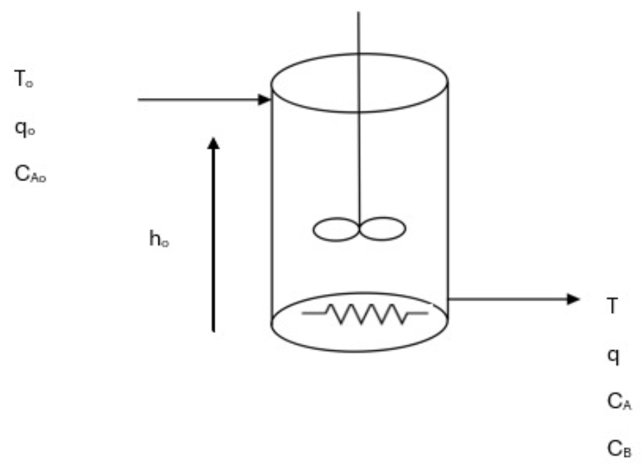

               Figura 1. Reactor Cilíndrico CSTR

Para resolver el ejemplo debemos considerar algunas ecuaciones como las siguientes:

**Balance de Masa General:**


$$\frac{d\left(\rho_{m\;} V\right)}{\textrm{dt}}=q_o \;\rho_{o\;} -q_s \;\rho_{s\;}$$


**Balance de Masa por especies:**

A


$$\frac{d\left(C_{A\;} V\right)}{\textrm{dt}}=q_o \;C_{\textrm{Ao}\;} -q_s \;C_A -k{\;C}_{A\;} V$$


B


$$\frac{d\left(C_{B\;} V\right)}{\textrm{dt}}=-q_s \;C_B +k{\;C}_{A\;} V$$


**Balance de Energia**


$$\rho_{m\;} V{\textrm{Cp}}_{m\;} \frac{\textrm{dT}}{\textrm{dt}}=q_o \;\rho_{m\;} {\textrm{Cp}}_{m\;} \left(T-T_{0\;} \right)-r_{A\;} V\;\left(-\Delta H_{\textrm{Rx}\;} \right)+\overset{\ldotp \ldotp }{Q}$$



$$\frac{\textrm{dT}}{\textrm{dt}}=\frac{\left(q_o \;\rho_{m\;} {\textrm{Cp}}_{m\;} \left(T-T_{0\;} \right)-r_{A\;} V\;\left(-\Delta H_{\textrm{Rx}\;} \right)+\textrm{UAt}*\left(T-T_{g\;} \right)\right)}{\rho_{m\;} V{\textrm{Cp}}_{m\;} }$$


Ecuación de Arhenius


$$k=A\;e^{-\frac{\textrm{Ea}}{\textrm{RT}}}$$


## Variables 

clc;clear;close

En esta sección se definen y varían las variables dadas en el problema 

## Reactor


Vt=45; %Volumen total del tanque [L] 
V=39.6; %Volumen utilizado [L]
h=3.5; % Altura del liquido [m]
% Reacción 
k=0.25; % cte de reacción T=100°C
delta_rx=-75000; % Entalpia de Reacción [kJ/mol]
% Condiciones del gas
Tg=50;                      % Temperatura del gas [°C]
U=10000                     % [kJ/sm2°C]

U = 10000

% Condiciones del líquido
Cp=3.5;                     % Capacidad calorífica [kJ/kgK]
densidad=950;               % [kg/m3]
Ea=600;                     % Energia de Activación [cal/mol]
R=1.987;                    % cte en [cal/mol K]
A = k/(exp((-Ea)/(R*373)))  % Factor de colisión

A = 0.5617

fprintf("%.15f", A)

0.561725079427792



% Parámetros de operación 
Cao=5000;                   % kmol/m3
Tf=100;                     % °C
To=120;
Vo=39.6;
q = 0.1;
Caf=50;                     % kmol/m3
CBinicial = 0.25*Caf*Vo/0.1;

## Solución en estado estacionario

Aquí se inicializará el valor de cada variable.

% Estado estacionario
t1 = 0;
deltat = 0.1;
for i = 1:10000
    t1(i+1) = t1(i) + deltat;
end

Tgrafico = 1:length(t1);
Tgrafico(1:end) = 100;

Vgrafico = 1:length(t1);
Vgrafico(1:end) = 39.6;

CAgrafico = 1:length(t1);
CAgrafico(1:end) = 50;

kgrafico = 1:length(t1);
kgrafico(1:end) = 0.25;

Tgrafico = 1:length(t1);
Tgrafico(1:end) = 100;

qgrafico = 1:length(t1);
qgrafico(1:end) = 0.1;

## Soluciones con perturbaciones 

% Perturbación Caudal de entrada
qperturbacion=input("Ingresar la perturbación del Caudal [L/min]: ")

qperturbacion = 0.1000

qo=q+qperturbacion;

### Escenario A:  

#### Perturbación en el caudal

% PERTURBACIÓN EN EL CAUDAL (ESCENARIO A)
% qo=0.2; %l/min
Afc=74.26; %m2
V = 39.6;
Ca = 50;
Cb = k(1)*Ca(1)*V(1)/qo;
T = 100;
k = 0.25;
t = 0;
deltat = 0.1;

for i = 1:10000
    V(i+1) = V(i) + (qo-q)*deltat;
    T(i+1) = T(i) + ((-qo*densidad*Cp*(T(i)-To)-k(i)*Ca(i)*V(i)*delta_rx-U*Afc*(T(i)-Tg))/(V(i)*densidad*Cp))*deltat;
    Ca(i+1) = Ca(i) + ((qo*Cao - Ca(i)*(q + k(i)*V(i))- Ca(i)*(qo-q))/V(i))*deltat;
    Cb(i+1) = Cb(i) + ((k(i)*Ca(i)*V(i) - q*Cb(i)- Cb(i)*(qo-q))/V(i))*deltat;
    k(i+1) = A*exp((-Ea)/(R*(T(i+1)+273)));
    t(i+1) = t(i) + deltat;
end

CB = 1:length(t1);
CB(1:end) = CBinicial;


#### Perturbación en la temperatura 

% PERTURBACIÓN DE LA TEMPERATURA (ESCENARIO A)
Tperturbacion=input("Ingresar la perturbación de Temperatura [ºC]: ")

Tperturbacion = 130

To2=To+Tperturbacion;
% To2 = 130;
qo1=0.1;                %l/min
Afc=74.26;              %m2
V3 = 39.6;
Ca3 = 50;
Cb3 = k(1)*Ca(1)*V(1)/0.1;
T3 = 100;
k3 = 0.25;
t3(1) = 0;
deltat = 0.1;
tf=100;
i=1;

while t3(i)<=tf
    V3(i+1) = V3(i) + (qo1-q)*deltat;
    T3(i+1) = T3(i) + ((-qo1*densidad*Cp*(T3(i)-To2)-k3(i)*Ca3(i)*V3(i)*delta_rx-U*Afc*(T3(i)-Tg))/(V3(i)*densidad*Cp))*deltat;
    Ca3(i+1) = Ca3(i) + ((qo1*Cao - Ca3(i)*(q + k3(i)*V3(i))- Ca3(i)*(qo1-q))/V3(i))*deltat;
    Cb3(i+1) = Cb3(i) + ((k3(i)*Ca3(i)*V3(i) - q*Cb3(i)- Cb3(i)*(qo1-q))/V3(i))*deltat;
    k3(i+1) = A*exp((-Ea)/(R*(T3(i+1)+273)));
    t3(i+1) = t3(i) + deltat;
    i=i+1;
end

## Gráficos

### Escenario A:  

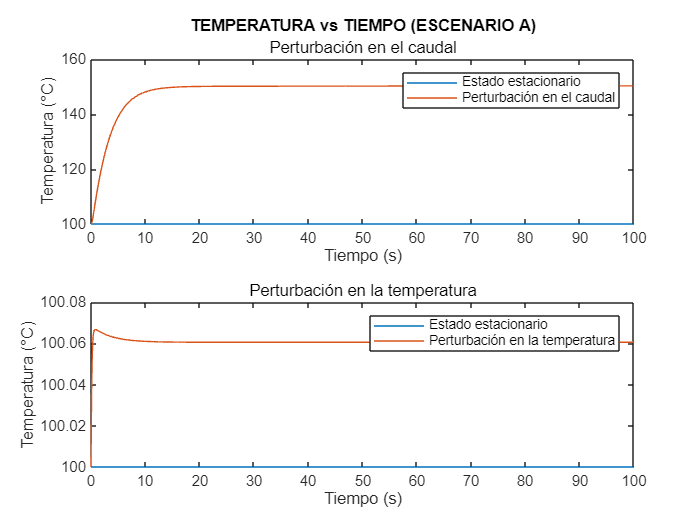

% Gráficos del escenario A

% Temperatura vs Tiempo
tiledlayout(2,1)
nexttile
plot(t1, Tgrafico)
hold on
plot(t,T)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en el caudal'
title('TEMPERATURA vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'Temperatura (°C)'
xlabel 'Tiempo (s)'
hold off

nexttile
plot(t1, Tgrafico)
hold on
plot(t3,T3)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en la temperatura'
title('','Perturbación en la temperatura');
ylabel 'Temperatura (°C)'
xlabel 'Tiempo (s)'
hold off

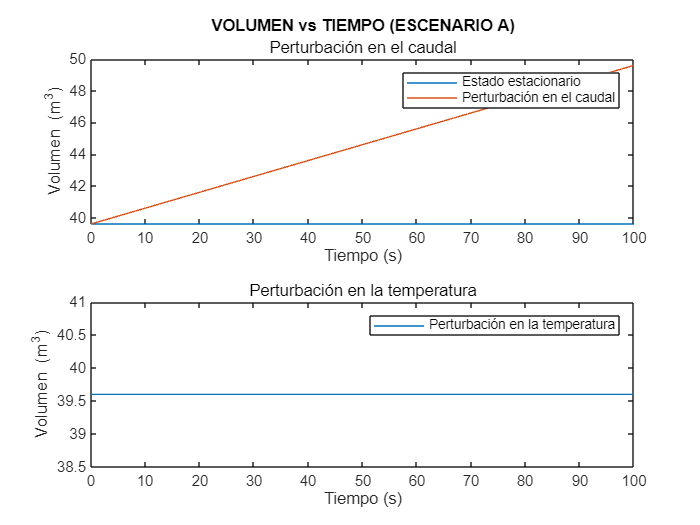

% Volumen vs Tiempo

tiledlayout(2,1)
nexttile
plot(t1, Vgrafico)
hold on
plot(t, V)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en el caudal'
title('VOLUMEN vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'Volumen (m^3)'
xlabel 'Tiempo (s)'
hold off


nexttile
plot(t3, V3)
xlim([0 100])
legend 'Perturbación en la temperatura'
title('','Perturbación en la temperatura');
ylabel 'Volumen (m^3)'
xlabel 'Tiempo (s)'

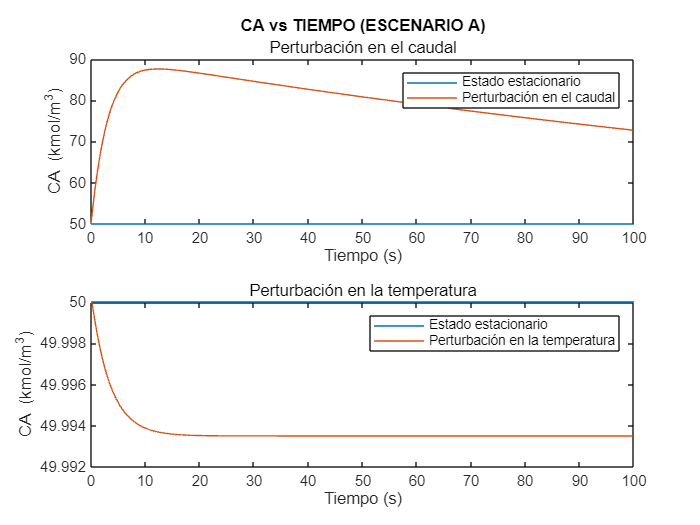

% CA vs Tiempo

tiledlayout(2,1)
nexttile
plot(t1, CAgrafico)
hold on 
plot(t, Ca)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en el caudal'
title('CA vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'CA (kmol/m^3)'
xlabel 'Tiempo (s)'
hold off

nexttile
plot(t1, CAgrafico)
hold on 
plot(t3, Ca3)
% ylim([30 100])
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en la temperatura'
title('','Perturbación en la temperatura');
ylabel 'CA (kmol/m^3)'
xlabel 'Tiempo (s)'
hold off

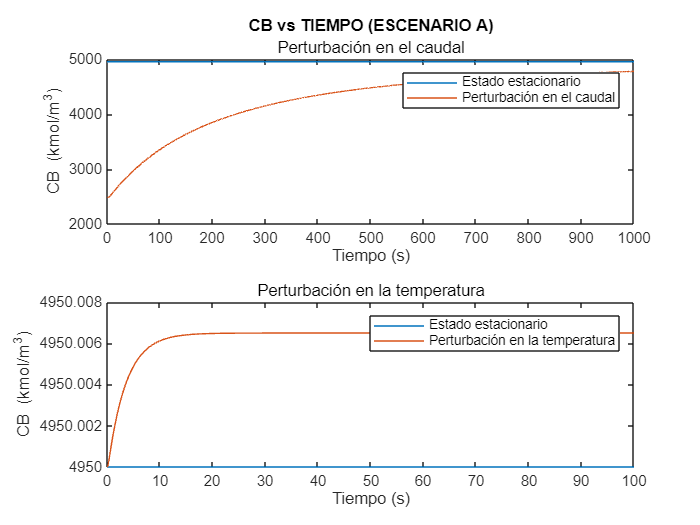

% CB vs Tiempo

tiledlayout(2,1)
nexttile
plot(t1, CB)
hold on
plot(t, Cb)
xlim([0 1000])
legend 'Estado estacionario' 'Perturbación en el caudal'
title('CB vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'CB (kmol/m^3)'
xlabel 'Tiempo (s)'
hold off

nexttile
plot(t1, CB)
hold on
plot(t3, Cb3)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en la temperatura'
title('','Perturbación en la temperatura');
ylabel 'CB (kmol/m^3)'
xlabel 'Tiempo (s)'
hold off

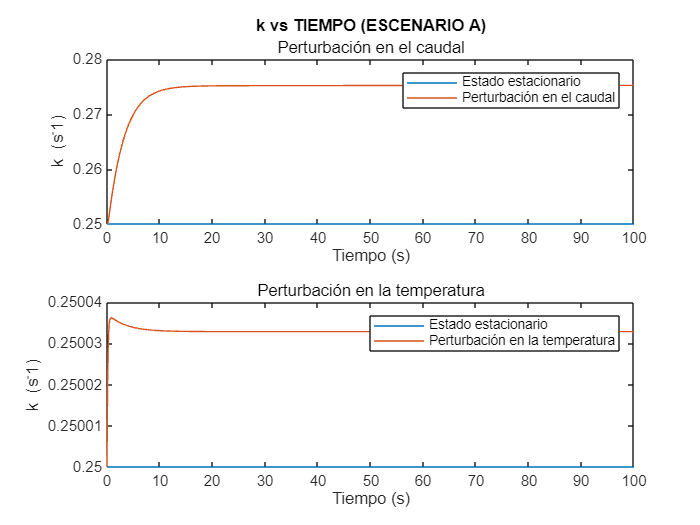

% k vs Tiempo

tiledlayout(2,1)
nexttile
plot(t1, kgrafico)
hold on 
plot(t, k)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en el caudal'
title('k vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'k (s^-1)'
xlabel 'Tiempo (s)'
hold off

nexttile
plot(t1, kgrafico)
hold on 
plot(t3, k3)
xlim([0 100])
legend 'Estado estacionario' 'Perturbación en la temperatura'
title('','Perturbación en la temperatura');
ylabel 'k (s^-1)'
xlabel 'Tiempo (s)'
hold off

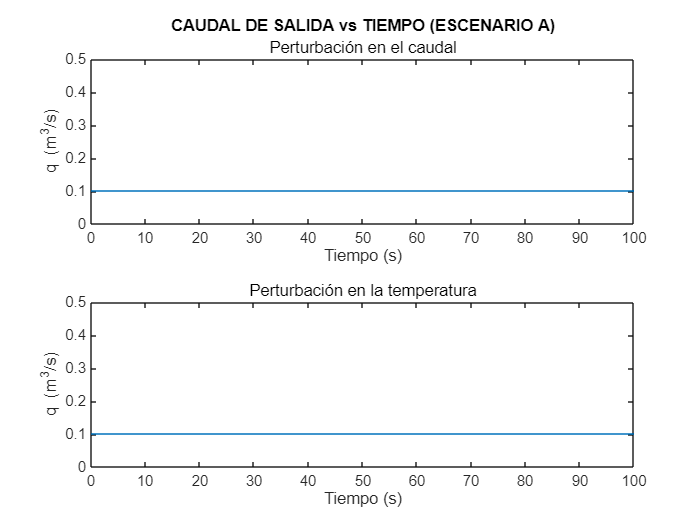

% Caudal de salida vs Tiempo

tiledlayout(2,1)
nexttile
plot(t1, qgrafico)
ylim([0 0.5])
xlim([0 100])
title('CAUDAL DE SALIDA vs TIEMPO (ESCENARIO A)','Perturbación en el caudal');
ylabel 'q (m^3/s)'
xlabel 'Tiempo (s)'

nexttile
plot(t1, qgrafico)
ylim([0 0.5])
xlim([0 100])
title('','Perturbación en la temperatura');
ylabel 'q (m^3/s)'
xlabel 'Tiempo (s)'

## Referencias

Achieng, E. (2014). Comparative Analysis of the Numerical Methods for solving Ordinary Differential Equations. African Institute for Mathematical Science. Cameroon.

Ahmed, Y., Yaakob, Z., Akhtar, P., & Sopian, K. (2015). Production of biogas and performance evaluation of existing treatment processes in palm oil mill effluent (POME). *Renewable and Sustainable Energy Reviews*, *42*, 1260-1278. https://doi.org/10.1016/j.rser.2014.10.073

Barragán, L. P., Figueroa, J., Durán, L. R., González, C. A., & Hennigs, C. (2016). Fermentative production methods. In *Elsevier eBooks* (pp. 189–217). https://doi.org/10.1016/b978-0-12-803622-8.00007-0

Boyadjiev, C. (2010). *Theoretical Chemical Engineering: Modeling and Simulation*. Springer Science & Business Media.

Kirsty (2023). *¿Cómo funciona un CSTR?* Asynt. https://www.asynt.com/es/blog/how-does-a-cstr-work/

Moran, S. (2017). Reactors. In *Elsevier eBooks* (pp. 355–368). https://doi.org/10.1016/b978-0-12-803355-5.00024-x

Saratale, G. D., Saratale, R. G., Banu, J. R., & Chang, J. (2019). Biohydrogen production from renewable biomass resources. In *Elsevier eBooks* (pp. 247–277). https://doi.org/10.1016/b978-0-444-64203-5.00010-1